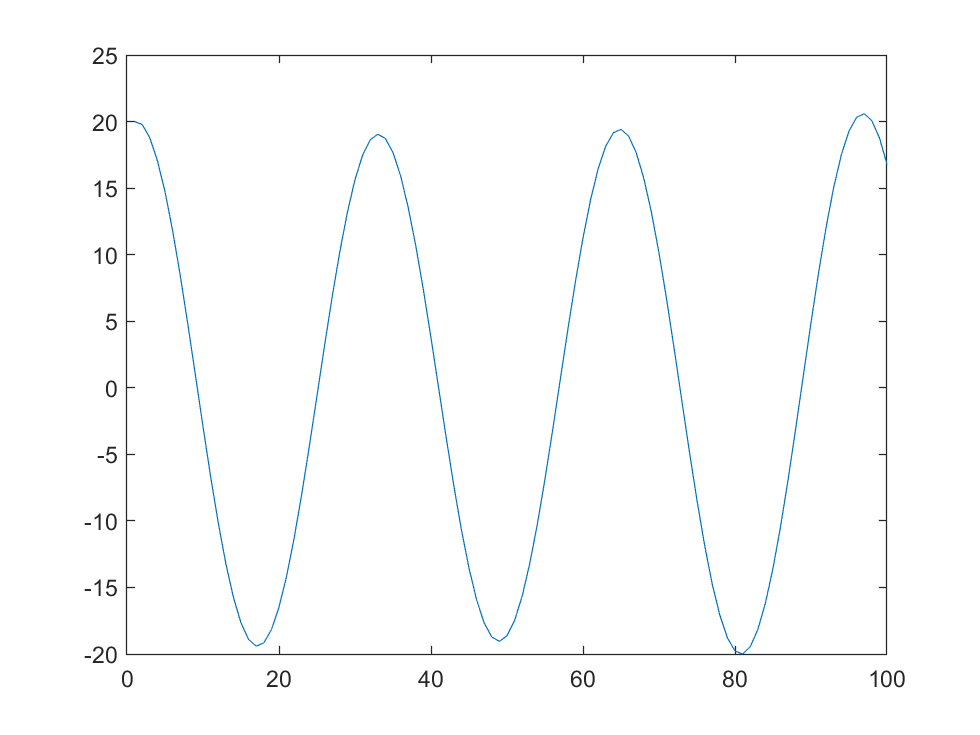

%ECOMMS Lab Project 1 Example 
%Dawson Tocarchick, Kyle Limbaga, Michael Johns
%Rowan University 
%This program generates a 1-second duration  
%Asharp signal (466.16 Hz) with a specified SNR

%Specify SNR 
snr=10; 

%Generate Asharp signal
t=[0:1/8e3:1.0]';

A_c = 20;
f_m = 200;
f_c = 250;
b = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Different Waveforms     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%s = 0.5*sin(2*pi*466.16*t);
%s = A_c*[1+cos(2*pi*f_m*t)].*(cos(2*pi*f_c*t));
s = A_c*cos(2*pi*f_c*t) + b*sin(2*pi*f_m*t);

plot(s);
xlim([0 100]);

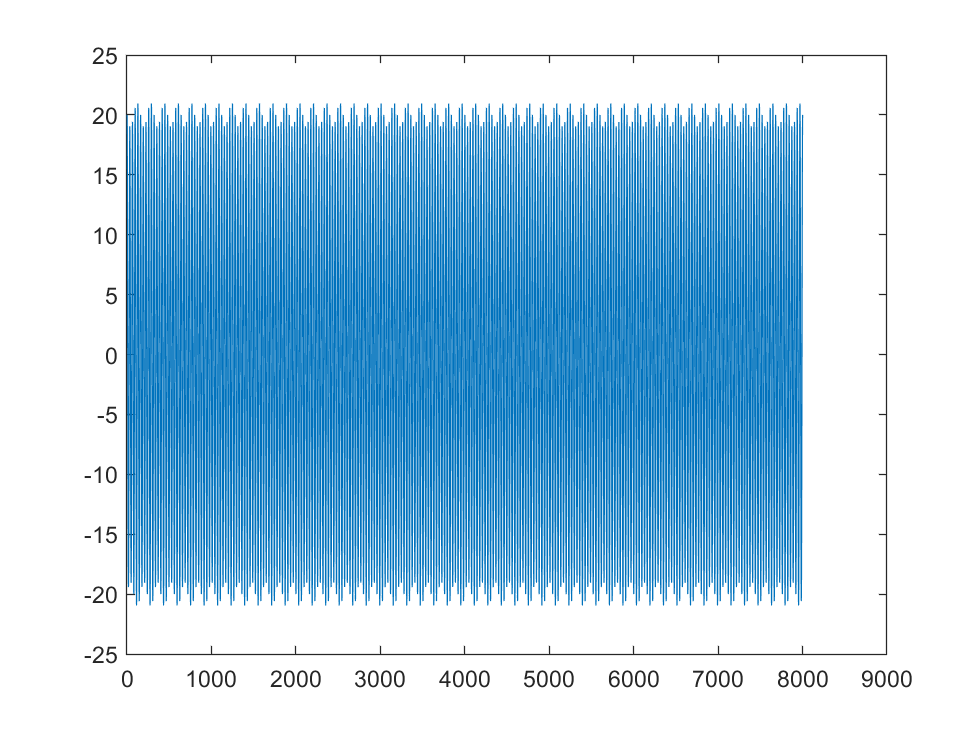


%sound(s); 

%Compute signal variance 
var_s = cov(s);

%Calculate required noise variance 
var_noise=var_s/(10^(snr/10)); 

%Generate noise 
n=sqrt(var_noise)*randn(length(s),1); %sound(n);

%Add signal to noise and generate message 
m=s+n; %sound(m); 

plot(s);

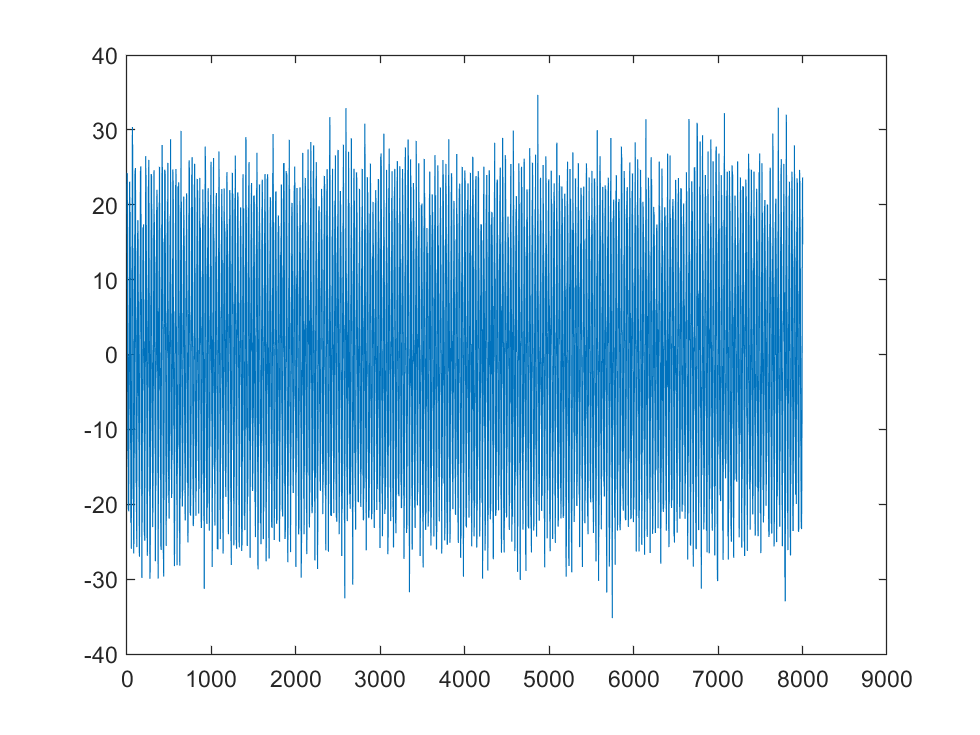

plot(m);

part 2:

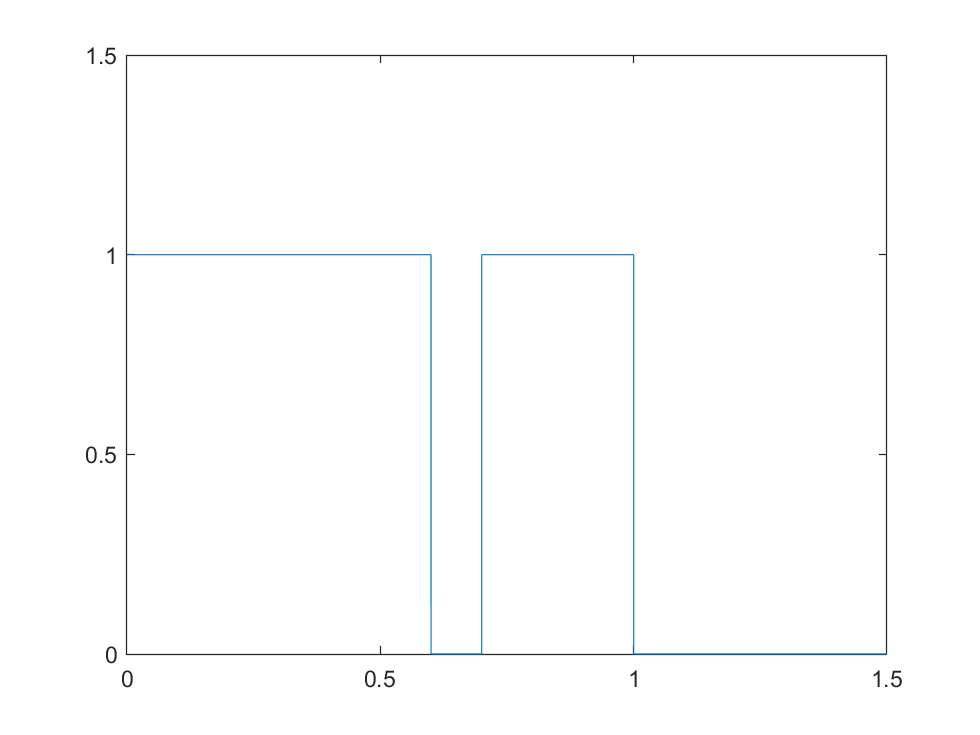

% syms x;
% fplot(heaviside([x-1;x]), [-2,2])

syms y(x)
y(x) = rectangularPulse(0,0.6,x)+rectangularPulse(0.7,1,x);

figure(1);
fplot(y);
axis([0 1.5 0 1.5]);

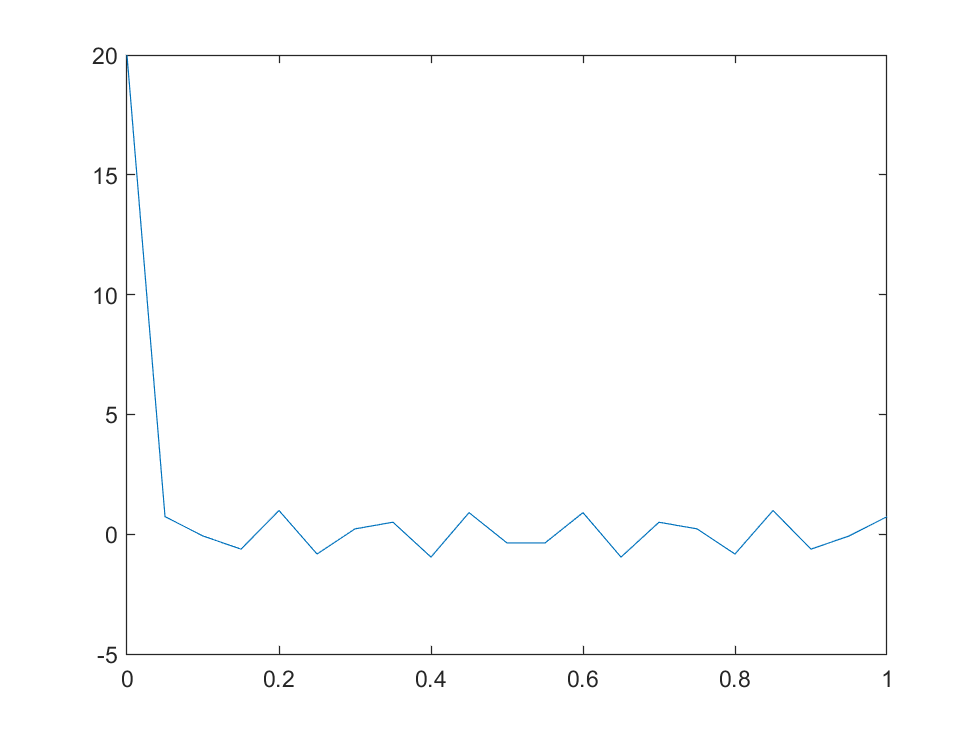


figure(2);
plot([0:0.05:1],fft(double(y([0:0.05:1]))));

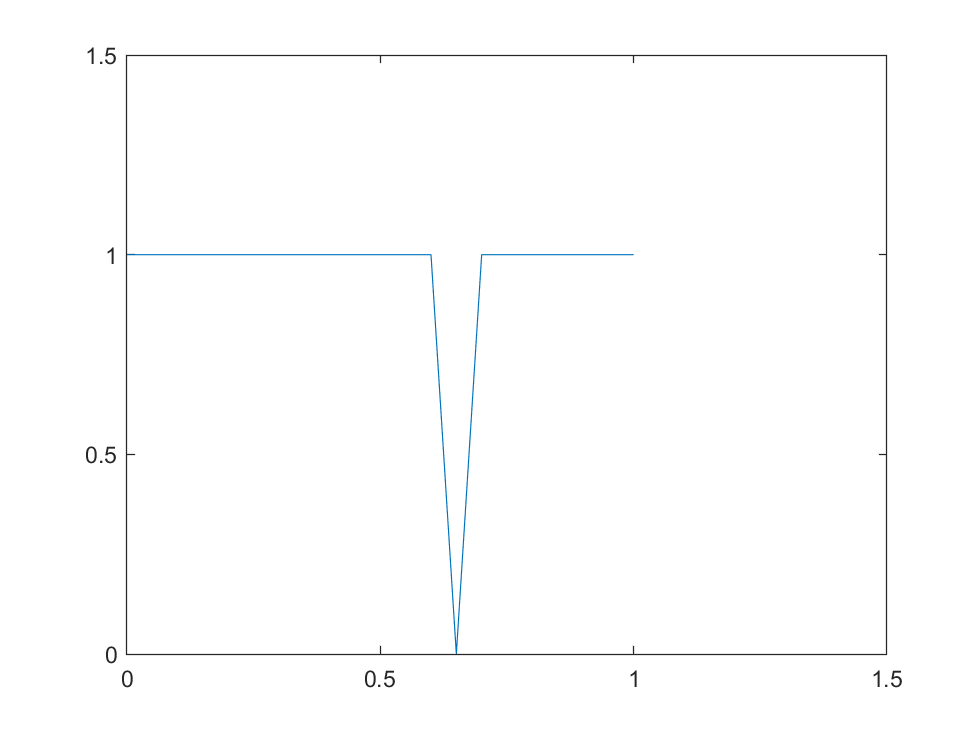


figure(3);
plot([0:0.05:1],ifft(fft(double(y([0:0.05:1])))));
axis([0 1.5 0 1.5]);

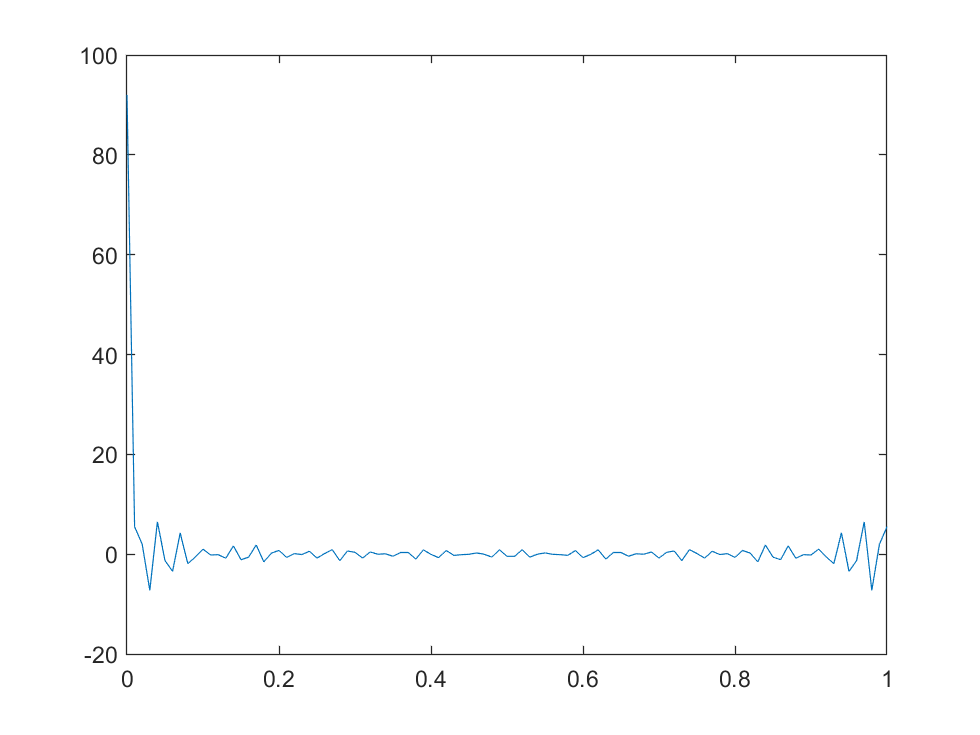


figure(4);
plot([0:0.01:1],fft(double(y([0:0.01:1]))));

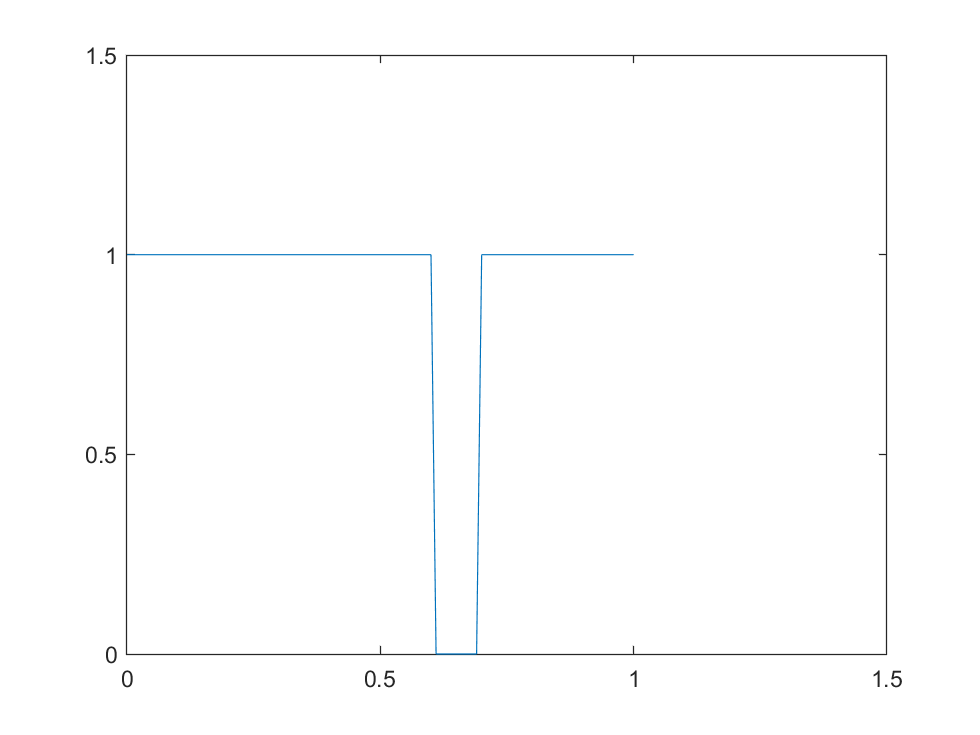


figure(5);
plot([0:0.01:1],ifft(fft(double(y([0:0.01:1])))));
axis([0 1.5 0 1.5]);

part 2 Kyle:

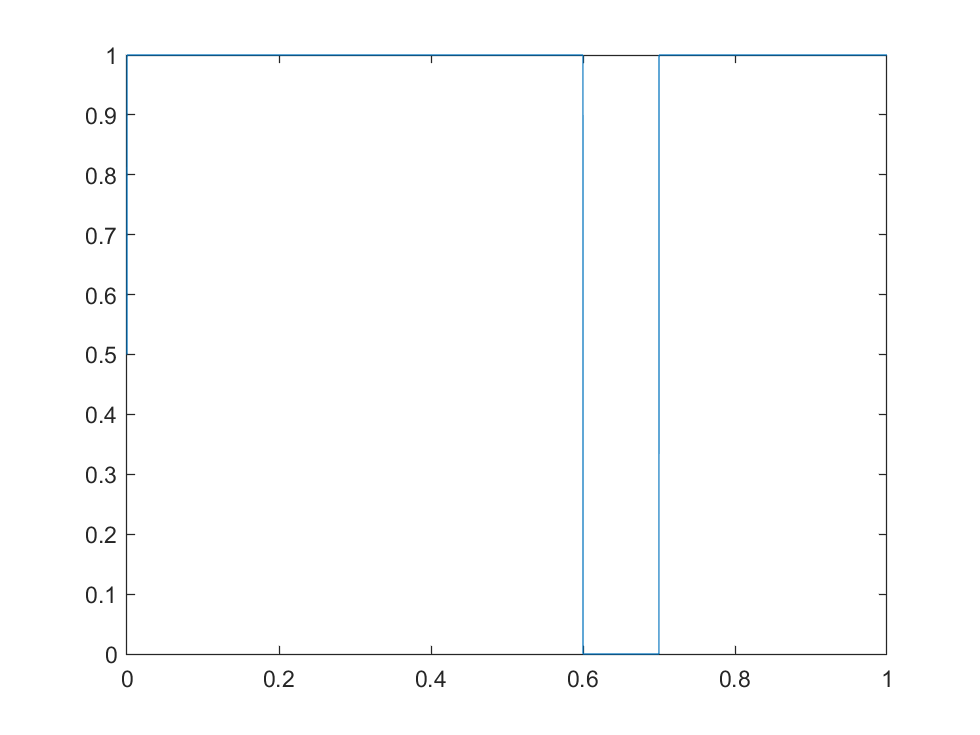

clf;
syms x;
fplot(heaviside([x-0.7]) - heaviside([x-0.6]) + heaviside([x]) , [0,1])


%Steps in millisecond
t = 0:0.01:1-0.01;
fs = 100;
sf = heaviside(t-0.7) - heaviside(t-0.6) + heaviside(t);
% sf = sinc(2*pi*10*t)
% plot(sf)
X = fft(sf)

X =   89.5000 + 0.0000i   5.2797 - 7.9551i   2.3870 + 8.8853i  -8.6396 - 2.6447i   5.5906 - 4.4251i  -0.5000 + 6.3138i  -4.5334 - 2.9305i   2.9422 - 1.1184i  -1.2074 + 2.1772i  -1.1252 - 0.8605i  -0.5000 + 0.0000i   0.0045 - 0.6944i  -0.0412 + 1.4119i  -2.2780 - 0.5777i   1.1351 - 1.1880i  -0.5000 + 1.9626i  -1.8996 - 1.0168i   0.8010 - 0.4227i  -0.7862 + 0.8809i  -0.7673 - 0.3679i  -0.5000 + 0.0000i  -0.2658 - 0.3223i  -0.2804 + 0.6757i  -1.3727 - 0.2836i   0.3194 - 0.5953i  -0.5000 + 1.0000i  -1.2225 - 0.5250i   0.1783 - 0.2204i  -0.6503 + 0.4625i  -0.6409 - 0.1939i  -0.5000 + 0.0000i  -0.3766 - 0.1699i  -0.3847 + 0.3548i  -0.9550 - 0.1478i  -0.0770 - 0.3073i  -0.5000 + 0.5095i  -0.8621 - 0.2631i  -0.1670 - 0.1082i  -0.5719 + 0.2213i  -0.5654 - 0.0900i  -0.5000 + 0.0000i  -0.4472 - 0.0726i  -0.4534 + 0.1435i  -0.6720 - 0.0559i  -0.3532 - 0.1066i  -0.5000 + 0.1584i  -0.5972 - 0.0706i  -0.4273 - 0.0236i  -0.5114 + 0.0352i  -0.5057 - 0.0079i


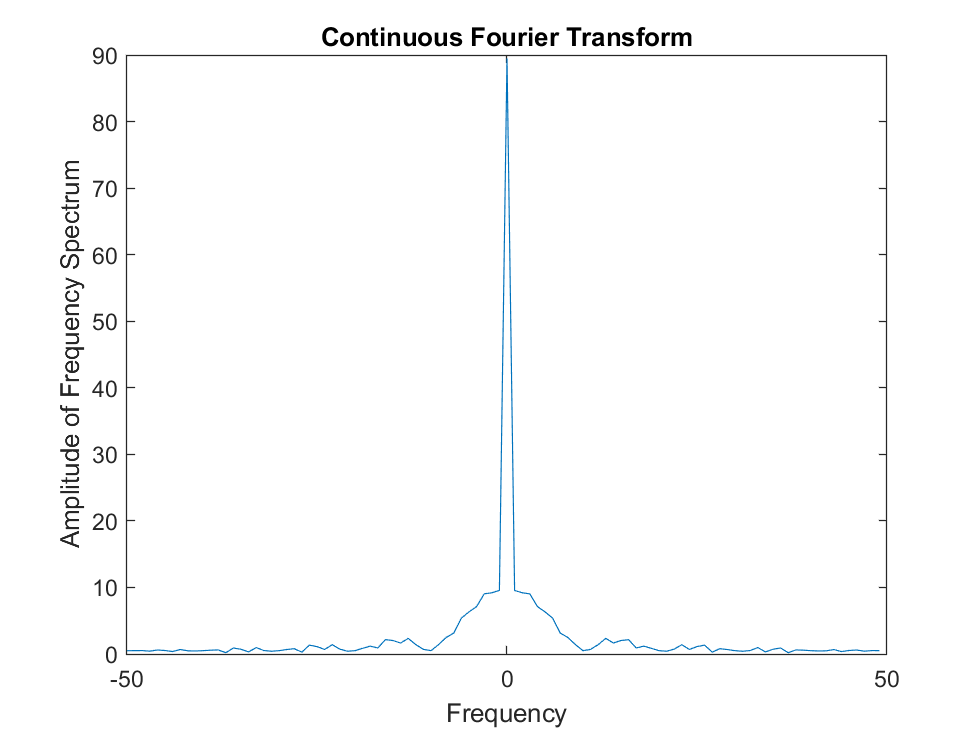

L = length(t); 

% f = (0:length(X)-1)*L/length(X);
% plot(f,abs(X))

X_shift = fftshift(X);
dF = fs/L;
f = -fs/2:dF:fs/2-dF;

Y = abs(X_shift);

plot(f,Y)
title('Continuous Fourier Transform')
ylabel('Amplitude of Frequency Spectrum')
xlabel('Frequency')

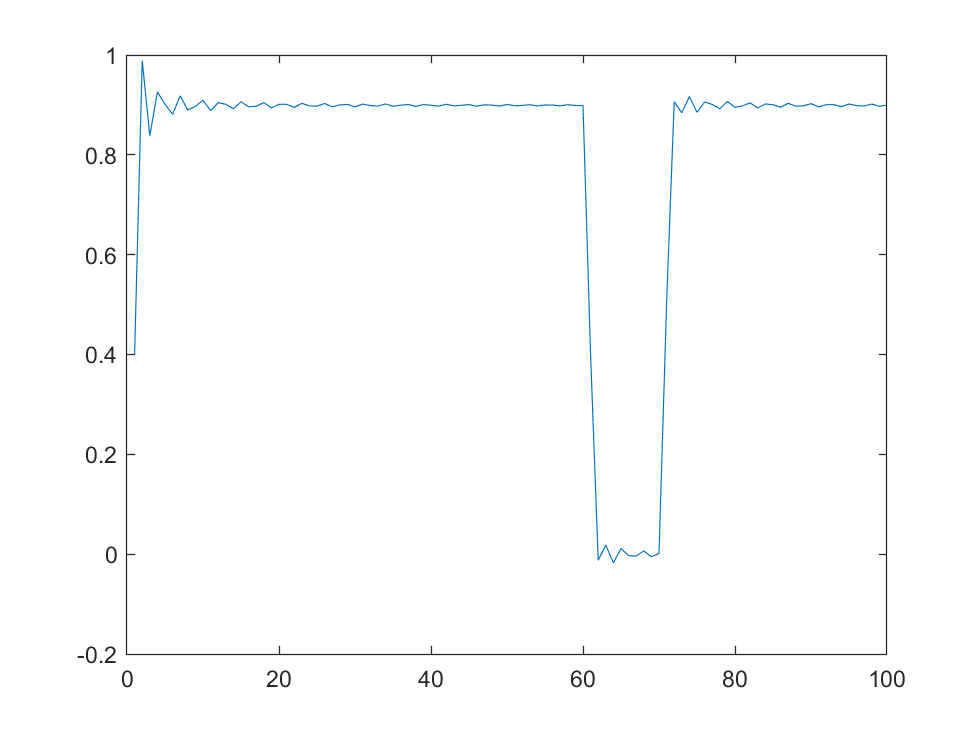



S = sinc(2*pi*20*t);
Xmag = abs(X);
Xphase = angle(X);
Smag = abs(fft(S));
Sphase = angle(fft(S));

fs2 = fftshift(fft(S));
inverse_fft = ifft(fft(S).*X);
plot(inverse_fft)

%Look at the graph at 10 Hz
% Minimum sampling frequency has to be 10.

ADDED STUFF BY DAWSON, TESTING OUT THINGS WITH SONGS


song = audioread('For_Love.mp3');
%sound(song, 44100)

fft(song)

ans = 	1.0e+05 *

   0.0251 + 0.0000i  -0.0048 + 0.0000i
  -0.0047 - 0.0027i  -0.0007 + 0.0013i
  -0.0021 - 0.0042i   0.0001 + 0.0011i
  -0.0021 - 0.0018i   0.0031 + 0.0028i
  -0.0027 - 0.0032i  -0.0016 - 0.0006i
   0.0010 - 0.0018i  -0.0013 - 0.0016i
  -0.0017 + 0.0048i   0.0002 - 0.0003i
   0.0001 + 0.0003i  -0.0012 + 0.0007i
   0.0004 + 0.0001i   0.0004 + 0.0002i
  -0.0025 + 0.0012i  -0.0026 + 0.0004i


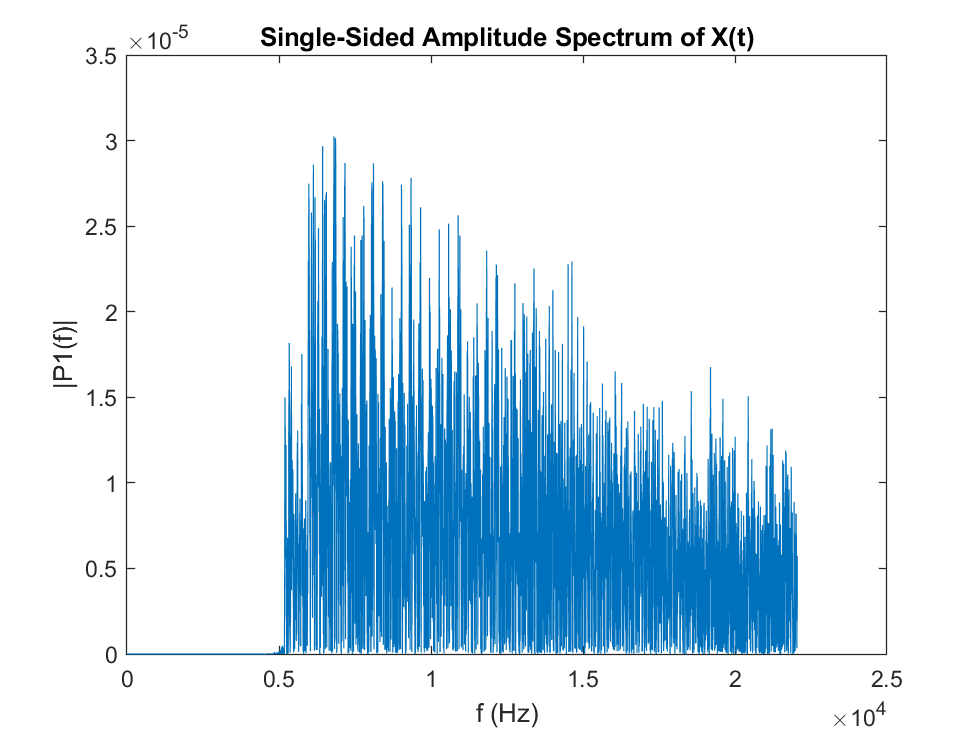

Fs = 44100;
T = 1/Fs;             % Sampling period       
L = 60000;             % Length of signal
t = (0:L-1)*T;        % Time vector

P2 = abs(song/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

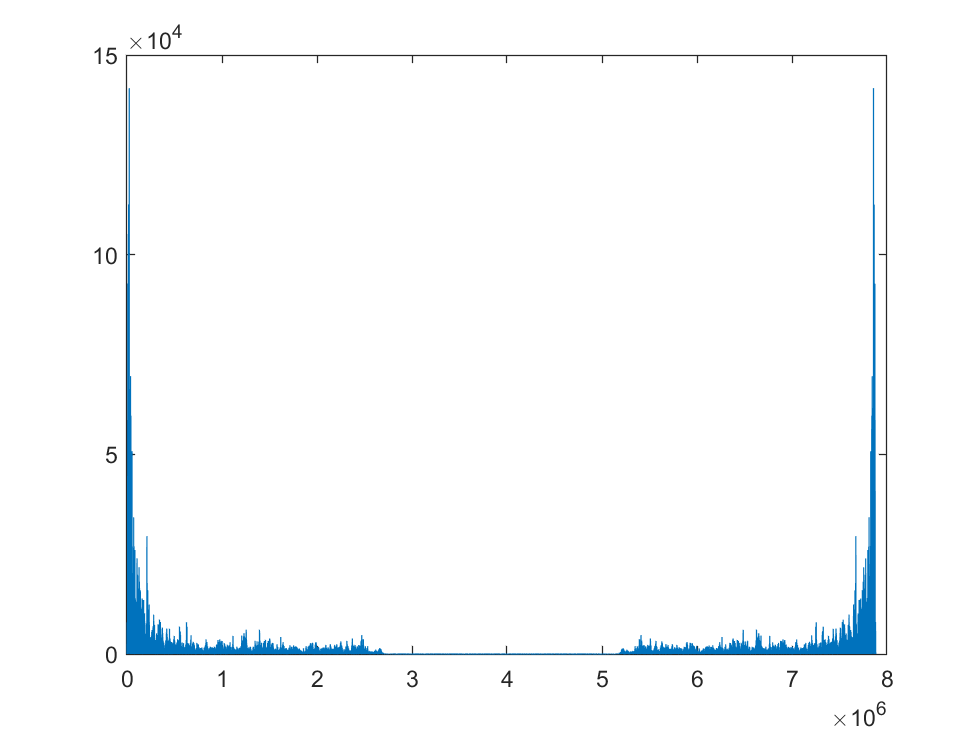



[data, fs] = audioread('For_Love.mp3');
data_fft = fft(data);
plot(abs(data_fft(:,1)))